# **FSIM (Functional SIMulator)**

**per ****f-HDGM**** e ****fp-HDGM**

Parametri da impostare:

- $\rho \ [1\times1]$;

- $\mathbf{c}_{\epsilon} \ [p_{\epsilon}\times 1]$;

- 
$$\mathbf{C}_{\beta} \ [b\times p_{\beta}]$$


- $\Sigma_0 \ [n\cdot p_z\times n\cdot p_z]$;

- $\mathbf{\mu}_0 \ [n\cdot p_z\times 1]$;

- $\mathbf{G} \ [p_z\times p_z]$;

- 
$$\mathbf{V} \ [p_z\times p_z]$$


- $\mathbf{\theta} \ [p_z\times 1]$;

- $n$, $q$, $b$ e $T$

addpath ..\'D-STEM v2.1'\Src\




clear all %#ok<CLALL> 
clc
rng('default')

#### **Scelta dei punti**

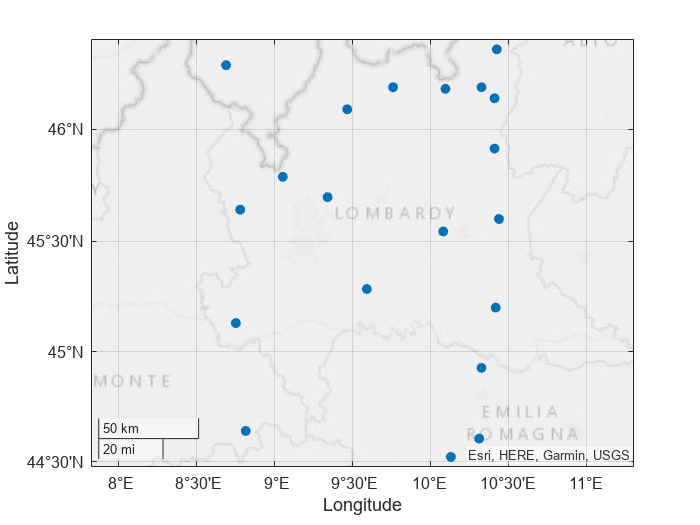

n = 20;
points = FSIM.get_points(n);
geoscatter(points, "Latitude", "Longitude", "filled")

#### Impostazione dei parametri

rng('default')

q = 24;
T = 365;
params.rho = 10;
n_basis.p_eps = 5;
n_basis.p_beta = 7;
n_basis.p_z = 7;

b = 2;
X = cell(T, 1);
for t=1:T
    X_t = ones(q*n, 2);
    for i=2:b
        X_t(:, 2) = randi(100, q*n, 1);
    end
    X{t} = X_t;
end

obj = FSIM(points, q, T, "NumBasis", n_basis, "Parameters", params);

FSIM (Functional SIMulator)
 
Authors: 
- Lorenzo LEONI
- Nicola ZAMBELLI
 
Dimensions: 
- n, q, b and T: [20 24 1 365]
- p_eps, p_beta and p_z: [5 7 7]
 
Parameters set: 
- rho: 10
- c_eps: [21   -0.0664489    -0.193816      1.22426    -0.304687]
- c_beta_1: [46  25  49  33  56  64  59]
- diag_G: [0.45398     0.50623     0.63056     0.20169     0.20303     0.16564     0.94144]
- diag_V: [2  5  5  2  8  7  8]
- theta: [36  36  36  36  36  36  36]


#### Avvio della/e simulazione/i

rng('default')
obj = obj.run(10);

Running simulation/s: 
- sim. 1 of 10 done.
- sim. 2 of 10 done.
- sim. 3 of 10 done.
- sim. 4 of 10 done.
- sim. 5 of 10 done.
- sim. 6 of 10 done.
- sim. 7 of 10 done.
- sim. 8 of 10 done.
- sim. 9 of 10 done.
- sim. 10 of 10 done.


**NB**: si ricorda che le osservazioni $Y_{sim}$ sono impilate prima per $q$, poi per $n$ (fissato $q$, viene espresso il valore di $y$ assunto presso le diverse $n$ stazioni).

#### Formattazione dei dati per rispettare la sintassi di D-STEM

data = obj.format_data;

Running data formatting: 
- dataset 1 of 10 done.
- dataset 2 of 10 done.
- dataset 3 of 10 done.
- dataset 4 of 10 done.
- dataset 5 of 10 done.
- dataset 6 of 10 done.
- dataset 7 of 10 done.
- dataset 8 of 10 done.
- dataset 9 of 10 done.
- dataset 10 of 10 done.


#### Validazione dei modelli spazio-temporali

Model type definition

o_modeltype = stem_modeltype('f-HDGM');
if obj.params.rho == 0
    o_modeltype.flag_potential = false;
else
    o_modeltype.flag_potential = true;
end

Basis configuration

input_fda.spline_type = 'Fourier';
input_fda.spline_range = [0 q];
input_fda.spline_nbasis_z = n_basis.p_z;
input_fda.spline_nbasis_beta = n_basis.p_beta; 
input_fda.spline_nbasis_sigma = n_basis.p_eps;
o_fda = stem_fda(input_fda);

Input data

input_data.stem_modeltype = o_modeltype;
input_data.data_table = data{1};
input_data.stem_fda = o_fda;
o_data = stem_data(input_data);

 
**********************************************
*   Data description of stem_varset object   *
**********************************************
Maximum number of observations per profile: q=24
 
Number of spatial locations: n=20
 
Number of time steps: T=365
 
Generating data matrices...
Generation ended.
Looking for duplicated sites...
Operation ended.


Input parameters

o_par = stem_par(o_data, 'exponential');

if obj.params.rho ~= 0
    o_par.rho = 10;
end

o_model = stem_model(o_data, o_par);

Generating data matrices...
Generation ended.


% if model is fp-HDGM, then from the observed data is removed
% the conditional component thanks to diag_H_inv before the parameters
% initialization
if o_modeltype.is('f-HDGM') && o_modeltype.flag_potential
    
    % input parameters
    T = size(o_model.stem_data.Y, 2);
    n = size(o_model.stem_data.stem_gridlist_p.grid{1, 1}.coordinate, 1);
    q = o_model.stem_par.q;
    o_model.set_distance_matrix
    Y=o_model.stem_data.Y;
    
    % diag_H_inv computation
    diag_H_inv = stem_misc.compute_H_inv(o_model.DistMat_rho, ...
        q, o_model.stem_par.rho);
    
    % update of Y
    Y_pot = zeros(size(o_model.stem_data.Y));
    for t=1:T
        Y_pot(:, t) = diag_H_inv.*Y(:, t);
    end
    o_model.stem_data.stem_varset_p.Y = mat2cell(Y_pot, n.*ones(1, q));
    o_model.stem_data.Y = Y_pot;
 
end

Generating point distance matrices...
Generation ended.


n_basis = o_fda.get_basis_number;

o_par.beta = o_model.get_beta0();
o_par.sigma_eps = o_model.get_coe_log_sigma_eps0();
o_par.theta_z = ones(1,n_basis.z)*40;
o_par.G = diag(ones(n_basis.z,1)*0.5);
o_par.v_z = eye(n_basis.z)*2;

o_model.set_initial_values(o_par);

o_model.stem_data.stem_varset_p.Y = mat2cell(Y, n.*ones(1, q));
o_model.stem_data.Y = Y;

Model estimation

% EM parameters
o_EM_options = stem_EM_options();
o_EM_options.exit_tol_par = 0.0001; 
o_EM_options.exit_tol_loglike = 0.0001; 
o_EM_options.max_iterations = 80;

% EM estimation
o_model.EM_estimate(o_EM_options);

Generating point distance matrices...
Generation ended.
 
**********************
*   D-STEM version   *
**********************
 
Model estimation is performed using D-STEM v2
 
******************************
*   Brief data description   *
******************************
Number of variables: q=24
 
Point variables:
sum of points for each variable: Nq=480
sum of sites for each variable: N=20
 
Date and time steps:
  Stating date  : 01-Jan-2023
  Ending date   : 31-Dec-2023
  Temporal steps: 365
 
Bounding box of the point data:
  Latitude min : 44.52 deg
  Latitude max : 46.35 deg
  Longitude min: 08.69 deg
  Longitude max: 10.44 deg
 
Number of latent variables: p=7
 
Covariates related to beta:
    {'const'}

************************
Iteration 1 started...
************************
  E step started...
    Kalman smoother started...
    Kalman smoother ended in 3.30s
    Xbeta evaluation started...
    Xbeta evaluation ended in 0.01s
    Conditional E, Var, Cov evaluation started...
    C

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.80s
****************
logL: -200757.0528
logL relative delta: 0.078036
Parameter delta norm: 0.13234
****************
PARAMETER VALUES
****************
beta: 44.1848      23.5402      47.6519      30.9584       54.153      61.0868      59.7698
sigma_eps: 5.8939   -0.053743    -0.19328      1.1765    -0.29371
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 28.4483      26.4506      29.3905      26.9626      30.7223      31.5543      32.0031
rho: 0.35204
v_z: 
    2.8683         0         0         0         0         0         0
         0    2.6844         0         0         0         0         0
         0         0    3.2469         0         0         0         0
         0         0         0    2.5689         0         0         0
         0         0         0         0    3.7

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.77s
****************
logL: -185140.5128
logL relative delta: 0.08435
Parameter delta norm: 0.15215
****************
PARAMETER VALUES
****************
beta: 44.1787      23.5372      47.6459       30.953      54.1486      61.0808      59.7656
sigma_eps: 4.9972   -0.054163    -0.19411      1.1763    -0.29365
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 29.0214        26.92      30.0801      27.3998      31.5212      32.4359      32.7676
rho: 0.32234
v_z: 
    2.8545         0         0         0         0         0         0
         0    2.5826         0         0         0         0         0
         0         0    3.2370         0         0         0         0
         0         0         0    2.5070         0         0         0
         0         0         0         0    3.75

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.78s
****************
logL: -169588.7864
logL relative delta: 0.091703
Parameter delta norm: 0.17878
****************
PARAMETER VALUES
****************
beta: 44.1735      23.5346      47.6408      30.9483      54.1448      61.0757      59.7621
sigma_eps: 4.1037   -0.054671    -0.19486      1.1761    -0.29359
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 29.7193      27.4599      30.9087      27.9275      32.4727      33.4943       33.699
rho: 0.29511
v_z: 
    2.8369         0         0         0         0         0         0
         0    2.4795         0         0         0         0         0
         0         0    3.2216         0         0         0         0
         0         0         0    2.4425         0         0         0
         0         0         0         0    3.7

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.86s
****************
logL: -154102.4923
logL relative delta: 0.10049
Parameter delta norm: 0.21696
****************
PARAMETER VALUES
****************
beta: 44.169      23.5323      47.6365      30.9443      54.1416      61.0715      59.7591
sigma_eps: 3.2134   -0.055183    -0.19563      1.1761    -0.29365
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 30.5553      28.0775      31.8897      28.5565      33.5953       34.749      34.8169
rho: 0.26995
v_z: 
    2.8151         0         0         0         0         0         0
         0    2.3757         0         0         0         0         0
         0         0    3.2003         0         0         0         0
         0         0         0    2.3758         0         0         0
         0         0         0         0    3.742

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.76s
****************
logL: -138681.6315
logL relative delta: 0.1112
Parameter delta norm: 0.27603
****************
PARAMETER VALUES
****************
beta: 44.1651      23.5302      47.6327      30.9407      54.1388      61.0678      59.7566
sigma_eps: 2.3264   -0.055701    -0.19624      1.1761    -0.29382
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 31.5454      28.7811      33.0421      29.2974      34.9088      36.2243      36.1421
rho: 0.24654
v_z: 
    2.7891         0         0         0         0         0         0
         0    2.2718         0         0         0         0         0
         0         0    3.1730         0         0         0         0
         0         0         0    2.3072         0         0         0
         0         0         0         0    3.724

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.84s
****************
logL: -123329.1197
logL relative delta: 0.12448
Parameter delta norm: 0.37976
****************
PARAMETER VALUES
****************
beta: 44.1618      23.5283      47.6295      30.9376      54.1365      61.0648      59.7545
sigma_eps: 1.4429   -0.056223    -0.19685      1.1761    -0.29405
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 32.7066      29.5805      34.3865      30.1627      36.4339      37.9466      37.6972
rho: 0.2246
v_z: 
    2.7586         0         0         0         0         0         0
         0    2.1687         0         0         0         0         0
         0         0    3.1399         0         0         0         0
         0         0         0    2.2370         0         0         0
         0         0         0         0    3.700

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.78s
****************
logL: -108041.1433
logL relative delta: 0.1415
Parameter delta norm: 0.60996
****************
PARAMETER VALUES
****************
beta: 44.1589      23.5266      47.6268      30.9349      54.1345      61.0622      59.7527
sigma_eps: 0.5628    -0.05675    -0.19739      1.1763     -0.2944
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 34.0565      30.4869      35.9443      31.1622      38.1992      39.9445      39.5134
rho: 0.20389
v_z: 
    2.7240         0         0         0         0         0         0
         0    2.0667         0         0         0         0         0
         0         0    3.1013         0         0         0         0
         0         0         0    2.1656         0         0         0
         0         0         0         0    3.668

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.75s
****************
logL: -92811.6456
logL relative delta: 0.16409
Parameter delta norm: 1.5584
****************
PARAMETER VALUES
****************
beta: 44.1565      23.5251      47.6244      30.9326      54.1327        61.06      59.7512
sigma_eps: -0.31427   -0.057371    -0.19785      1.1765    -0.29491
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 35.6196      31.5084      37.7385      32.3133      40.2285      42.2565      41.6213
rho: 0.18417
v_z: 
    2.6854         0         0         0         0         0         0
         0    1.9667         0         0         0         0         0
         0         0    3.0576         0         0         0         0
         0         0         0    2.0937         0         0         0
         0         0         0         0    3.62

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.86s
****************
logL: -77633.4891
logL relative delta: 0.19551
Parameter delta norm: 2.7822
****************
PARAMETER VALUES
****************
beta: 44.1543      23.5238      47.6224      30.9305      54.1313      61.0581        59.75
sigma_eps: -1.1886   -0.057909    -0.19824      1.1768    -0.29561
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 37.4158      32.6568      39.7999       33.628      42.5576       44.921      44.0579
rho: 0.16528
v_z: 
    2.6433         0         0         0         0         0         0
         0    1.8690         0         0         0         0         0
         0         0    3.0094         0         0         0         0
         0         0         0    2.0215         0         0         0
         0         0         0         0    3.584

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.80s
****************
logL: -62533.8199
logL relative delta: 0.24146
Parameter delta norm: 0.73169
****************
PARAMETER VALUES
****************
beta: 44.1525      23.5226      47.6206      30.9287        54.13      61.0565      59.7489
sigma_eps: -2.0584   -0.058451    -0.19855      1.1774    -0.29647
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 39.4721      33.9433      42.1542      35.1236      45.2257      47.9836      46.8636
rho: 0.14709
v_z: 
    2.5980         0         0         0         0         0         0
         0    1.7741         0         0         0         0         0
         0         0    2.9575         0         0         0         0
         0         0         0    1.9498         0         0         0
         0         0         0         0    3.53

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.80s
****************
logL: -47564.527
logL relative delta: 0.31472
Parameter delta norm: 0.41875
****************
PARAMETER VALUES
****************
beta: 44.1509      23.5216      47.6191      30.9272       54.129      61.0552       59.748
sigma_eps: -2.9203   -0.059091    -0.19878       1.178    -0.29763
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 41.8167      35.3778       44.835       36.814      48.2698      51.4934      50.0813
rho: 0.12946
v_z: 
    2.5504         0         0         0         0         0         0
         0    1.6826         0         0         0         0         0
         0         0    2.9028         0         0         0         0
         0         0         0    1.8790         0         0         0
         0         0         0         0    3.479

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.79s
****************
logL: -32827.0537
logL relative delta: 0.44894
Parameter delta norm: 0.29033
****************
PARAMETER VALUES
****************
beta: 44.1495      23.5206      47.6178      30.9258       54.128       61.054      59.7472
sigma_eps: -3.7681   -0.059737    -0.19894       1.179    -0.29908
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 44.4742      36.9711      47.8724      38.7153      51.7277      55.4964      53.7556
rho: 0.11233
v_z: 
    2.5012         0         0         0         0         0         0
         0    1.5950         0         0         0         0         0
         0         0    2.8464         0         0         0         0
         0         0         0    1.8097         0         0         0
         0         0         0         0    3.42

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.77s
****************
logL: -18516.1108
logL relative delta: 0.77289
Parameter delta norm: 0.21812
****************
PARAMETER VALUES
****************
beta: 44.1484      23.5198      47.6167      30.9246      54.1272      61.0531      59.7466
sigma_eps: -4.59    -0.06039    -0.19909      1.1805    -0.30089
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 47.4717      38.7289      51.2943       40.838      55.6303      60.0427      57.9255
rho: 0.095645
v_z: 
    2.4516         0         0         0         0         0         0
         0    1.5116         0         0         0         0         0
         0         0    2.7898         0         0         0         0
         0         0         0    1.7427         0         0         0
         0         0         0         0    3.363

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.91s
****************
logL: -4946.3165
logL relative delta: 2.7434
Parameter delta norm: 0.16931
****************
PARAMETER VALUES
****************
beta: 44.1473       23.519      47.6157      30.9236      54.1266      61.0522       59.746
sigma_eps: -5.3672   -0.061051    -0.19917      1.1824    -0.30307
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 50.8142      40.6489      55.1133      43.1811      60.0018      65.1659      62.6178
rho: 0.079362
v_z: 
    2.4031         0         0         0         0         0         0
         0    1.4332         0         0         0         0         0
         0         0    2.7347         0         0         0         0
         0         0         0    1.6790         0         0         0
         0         0         0         0    3.306

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.82s
****************
logL: 7432.485
logL relative delta: 1.6655
Parameter delta norm: 0.13156
****************
PARAMETER VALUES
****************
beta: 44.1464      23.5183      47.6149      30.9227       54.126      61.0515      59.7456
sigma_eps: -6.0733   -0.061814    -0.19917      1.1851    -0.30573
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 54.4939      42.7184      59.3116      45.7305      64.8348      70.8675      67.8292
rho: 0.063439
v_z: 
    2.3576         0         0         0         0         0         0
         0    1.3606         0         0         0         0         0
         0         0    2.6834         0         0         0         0
         0         0         0    1.6196         0         0         0
         0         0         0         0    3.2522 

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.82s
****************
logL: 18003.4004
logL relative delta: 0.58716
Parameter delta norm: 0.098706
****************
PARAMETER VALUES
****************
beta: 44.1456      23.5177      47.6141      30.9218      54.1254      61.0508      59.7451
sigma_eps: -6.6727    -0.06249    -0.19925      1.1884    -0.30866
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 58.4672      44.9026      63.8455      48.4502      70.0814      77.1015      73.5084
rho: 0.047994
v_z: 
    2.3174         0         0         0         0         0         0
         0    1.2946         0         0         0         0         0
         0         0    2.6387         0         0         0         0
         0         0         0    1.5660         0         0         0
         0         0         0         0    3.2

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.93s
****************
logL: 25998.6414
logL relative delta: 0.30753
Parameter delta norm: 0.086321
****************
PARAMETER VALUES
****************
beta: 44.1449      23.5171      47.6134      30.9211       54.125      61.0502      59.7448
sigma_eps: -7.1228   -0.063174    -0.19932       1.192    -0.31173
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 62.6521      47.1421      68.6222      51.2695      75.6347       83.757      79.5388
rho: 0.033427
v_z: 
    2.2852         0         0         0         0         0         0
         0    1.2362         0         0         0         0         0
         0         0    2.6035         0         0         0         0
         0         0         0    1.5196         0         0         0
         0         0         0         0    3.1

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.93s
****************
logL: 30897.0298
logL relative delta: 0.15854
Parameter delta norm: 0.082464
****************
PARAMETER VALUES
****************
beta: 44.1442      23.5165      47.6128      30.9204      54.1245      61.0497      59.7444
sigma_eps: -7.3967   -0.063667    -0.19956      1.1956    -0.31459
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 66.931      49.3567       73.514      54.0997      81.3479       90.664      85.7477
rho: 0.016544
v_z: 
    2.2631         0         0         0         0         0         0
         0    1.1862         0         0         0         0         0
         0         0    2.5803         0         0         0         0
         0         0         0    1.4817         0         0         0
         0         0         0         0    3.14

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.94s
****************
logL: 33358.5827
logL relative delta: 0.073791
Parameter delta norm: 0.077697
****************
PARAMETER VALUES
****************
beta: 44.1436       23.516      47.6121      30.9197      54.1241      61.0492      59.7441
sigma_eps: -7.5333   -0.064264    -0.19964      1.1982    -0.31674
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 71.2331      51.4973      78.4345      56.8835      87.1262      97.7082      92.0189
rho: 0.0017334
v_z: 
    2.2511         0         0         0         0         0         0
         0    1.1445         0         0         0         0         0
         0         0    2.5691         0         0         0         0
         0         0         0    1.4521         0         0         0
         0         0         0         0    3

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.01s
  M step ended in 0.96s
****************
logL: 33698.0991
logL relative delta: 0.010075
Parameter delta norm: 0.072478
****************
PARAMETER VALUES
****************
beta: 44.1429      23.5154      47.6115       30.919      54.1237      61.0487      59.7438
sigma_eps: -7.5491   -0.064415    -0.19979      1.1993    -0.31736
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 75.49942      53.51301      83.32116      59.57739      92.88667      104.7899      98.26644
rho: 0.0017334
v_z: 
    2.2483         0         0         0         0         0         0
         0    1.1104         0         0         0         0         0
         0         0    2.5688         0         0         0         0
         0         0         0    1.4303         0         0         0
         0         0         0        

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 0.86s
****************
logL: 33810.3628
logL relative delta: 0.0033204
Parameter delta norm: 0.068394
****************
PARAMETER VALUES
****************
beta: 44.1423      23.5148      47.6109      30.9183      54.1233      61.0482      59.7435
sigma_eps: -7.5476   -0.064515    -0.19979      1.1991    -0.31743
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 79.76834      55.42878      88.21896      62.20802       98.6812      111.9569       104.557
rho: 0.0017334
v_z: 
    2.2521         0         0         0         0         0         0
         0    1.0824         0         0         0         0         0
         0         0    2.5760         0         0         0         0
         0         0         0    1.4143         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.02s
****************
logL: 33910.7044
logL relative delta: 0.002959
Parameter delta norm: 0.064913
****************
PARAMETER VALUES
****************
beta: 44.1417      23.5142      47.6103      30.9176      54.1229      61.0478      59.7432
sigma_eps: -7.5453   -0.064616    -0.19971      1.1989     -0.3173
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 84.04508      57.25112      93.13683      64.77838      104.5228      119.2243      110.9085
rho: 0.0017334
v_z: 
    2.2609         0         0         0         0         0         0
         0    1.0593         0         0         0         0         0
         0         0    2.5889         0         0         0         0
         0         0         0    1.4031         0         0         0
         0         0         0        

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.06s
****************
logL: 34001.8002
logL relative delta: 0.0026791
Parameter delta norm: 0.06177
****************
PARAMETER VALUES
****************
beta: 44.1411      23.5136      47.6097      30.9169      54.1225      61.0473      59.7429
sigma_eps: -7.5432   -0.064667    -0.19971      1.1986    -0.31724
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 88.33828      58.99119      98.07812      67.29987      110.4133      126.5888      117.3218
rho: 0.0017334
v_z: 
    2.2737         0         0         0         0         0         0
         0    1.0403         0         0         0         0         0
         0         0    2.6063         0         0         0         0
         0         0         0    1.3957         0         0         0
         0         0         0        

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.29s
****************
logL: 34085.1891
logL relative delta: 0.0024465
Parameter delta norm: 0.058995
****************
PARAMETER VALUES
****************
beta: 44.1404       23.513      47.6091      30.9162      54.1221      61.0468      59.7426
sigma_eps: -7.5412   -0.064768    -0.19964      1.1983    -0.31718
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 92.64399      60.65253      103.0478      69.77525      116.3566       134.057      123.7998
rho: 0.0017334
v_z: 
    2.2897         0         0         0         0         0         0
         0    1.0247         0         0         0         0         0
         0         0    2.6273         0         0         0         0
         0         0         0    1.3914         0         0         0
         0         0         0       

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.46s
****************
logL: 34162.0179
logL relative delta: 0.002249
Parameter delta norm: 0.056425
****************
PARAMETER VALUES
****************
beta: 44.1398      23.5124      47.6086      30.9155      54.1217      61.0464      59.7424
sigma_eps: -7.5395   -0.064818    -0.19964      1.1981    -0.31705
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 96.96716      62.23819      108.0394      72.20677        122.35      141.6211      130.3384
rho: 0.0017334
v_z: 
    2.3083         0         0         0         0         0         0
         0    1.0120         0         0         0         0         0
         0         0    2.6512         0         0         0         0
         0         0         0    1.3898         0         0         0
         0         0         0        

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.12s
****************
logL: 34233.1356
logL relative delta: 0.0020775
Parameter delta norm: 0.054139
****************
PARAMETER VALUES
****************
beta: 44.1392      23.5118       47.608      30.9148      54.1214      61.0459      59.7421
sigma_eps: -7.538   -0.064869    -0.19964      1.1979    -0.31699
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 101.3008      63.75661      113.0621      74.59936      128.3959      149.2883      136.9474
rho: 0.0017334
v_z: 
    2.3290         0         0         0         0         0         0
         0    1.0017         0         0         0         0         0
         0         0    2.6773         0         0         0         0
         0         0         0    1.3903         0         0         0
         0         0         0        

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.41s
****************
logL: 34299.3128
logL relative delta: 0.0019294
Parameter delta norm: 0.051963
****************
PARAMETER VALUES
****************
beta: 44.1386      23.5111      47.6074      30.9141       54.121      61.0454      59.7418
sigma_eps: -7.5365    -0.06492    -0.19964      1.1977    -0.31693
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 105.6518      65.21533      118.1113      76.95656      134.4867      157.0457      143.6183
rho: 0.0017334
v_z: 
    2.3514         0         0         0         0         0         0
         0    0.9935         0         0         0         0         0
         0         0    2.7053         0         0         0         0
         0         0         0    1.3927         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.24s
****************
logL: 34361.1
logL relative delta: 0.0017982
Parameter delta norm: 0.049971
****************
PARAMETER VALUES
****************
beta: 44.1379      23.5105      47.6068      30.9134      54.1206       61.045      59.7416
sigma_eps: -7.5352    -0.06497    -0.19964      1.1975    -0.31687
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 110.0189      66.61704      123.1843      79.27987      140.6255      164.8935      150.3458
rho: 0.0017334
v_z: 
    2.3751         0         0         0         0         0         0
         0    0.9871         0         0         0         0         0
         0         0    2.7347         0         0         0         0
         0         0         0    1.3966         0         0         0
         0         0         0         0

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.21s
****************
logL: 34418.9684
logL relative delta: 0.0016813
Parameter delta norm: 0.048111
****************
PARAMETER VALUES
****************
beta: 44.1373      23.5098      47.6062      30.9127      54.1202      61.0446      59.7413
sigma_eps: -7.5341   -0.065021    -0.19964      1.1973    -0.31681
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 114.3966      67.96561      128.2815      81.57231      146.8115      172.8267      157.1276
rho: 0.0017334
v_z: 
    2.3999         0         0         0         0         0         0
         0    0.9821         0         0         0         0         0
         0         0    2.7653         0         0         0         0
         0         0         0    1.4017         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.19s
****************
logL: 34473.3111
logL relative delta: 0.0015764
Parameter delta norm: 0.046391
****************
PARAMETER VALUES
****************
beta: 44.1367      23.5092      47.6056      30.9121      54.1199      61.0441      59.7411
sigma_eps: -7.5329   -0.065021    -0.19964      1.1972    -0.31674
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 118.7876      69.26601      133.3978      83.83844      153.0378      180.8442       163.965
rho: 0.0017334
v_z: 
    2.4255         0         0         0         0         0         0
         0    0.9785         0         0         0         0         0
         0         0    2.7967         0         0         0         0
         0         0         0    1.4079         0         0         0
         0         0         0       

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.15s
****************
logL: 34524.478
logL relative delta: 0.001482
Parameter delta norm: 0.044751
****************
PARAMETER VALUES
****************
beta: 44.1361      23.5085      47.6051      30.9114      54.1195      61.0437      59.7408
sigma_eps: -7.5318   -0.065072    -0.19956       1.197    -0.31668
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 123.1898      70.52066      138.5383      86.07514      159.3092      188.9373      170.8527
rho: 0.0017334
v_z: 
    2.4518         0         0         0         0         0         0
         0    0.9759         0         0         0         0         0
         0         0    2.8289         0         0         0         0
         0         0         0    1.4150         0         0         0
         0         0         0         

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.23s
****************
logL: 34572.7544
logL relative delta: 0.0013964
Parameter delta norm: 0.043199
****************
PARAMETER VALUES
****************
beta: 44.1356      23.5079      47.6045      30.9107      54.1191      61.0433      59.7406
sigma_eps: -7.5309   -0.065123    -0.19956      1.1969    -0.31662
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 127.6031      71.73637      143.6938      88.28926      165.6137      197.0992      177.7872
rho: 0.0017334
v_z: 
    2.4786         0         0         0         0         0         0
         0    0.9743         0         0         0         0         0
         0         0    2.8615         0         0         0         0
         0         0         0    1.4229         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.41s
****************
logL: 34618.3848
logL relative delta: 0.0013181
Parameter delta norm: 0.04174
****************
PARAMETER VALUES
****************
beta: 44.135      23.5072      47.6039        30.91      54.1188      61.0429      59.7404
sigma_eps: -7.53   -0.065174    -0.19956      1.1967    -0.31656
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 132.0286      72.91337      148.8648      90.47937      171.9506      205.3261      184.7679
rho: 0.0017334
v_z: 
    2.5059         0         0         0         0         0         0
         0    0.9735         0         0         0         0         0
         0         0    2.8945         0         0         0         0
         0         0         0    1.4313         0         0         0
         0         0         0         0 

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.72s
****************
logL: 34661.5898
logL relative delta: 0.0012465
Parameter delta norm: 0.040377
****************
PARAMETER VALUES
****************
beta: 44.1344      23.5066      47.6034      30.9093      54.1184      61.0425      59.7401
sigma_eps: -7.5291   -0.065174    -0.19956      1.1966     -0.3165
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 136.4613      74.05608      154.0535      92.64448      178.3213      213.6166      191.7964
rho: 0.0017334
v_z: 
    2.5333         0         0         0         0         0         0
         0    0.9734         0         0         0         0         0
         0         0    2.9278         0         0         0         0
         0         0         0    1.4402         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.35s
****************
logL: 34702.5754
logL relative delta: 0.0011811
Parameter delta norm: 0.039049
****************
PARAMETER VALUES
****************
beta: 44.1338      23.5059      47.6028      30.9087      54.1181      61.0421      59.7399
sigma_eps: -7.5284   -0.065225    -0.19956      1.1965    -0.31643
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 140.8966      75.16563      159.2547      94.78929      184.7183      221.9582      198.8517
rho: 0.0017334
v_z: 
    2.5610         0         0         0         0         0         0
         0    0.9739         0         0         0         0         0
         0         0    2.9613         0         0         0         0
         0         0         0    1.4496         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.41s
****************
logL: 34741.4746
logL relative delta: 0.0011197
Parameter delta norm: 0.037827
****************
PARAMETER VALUES
****************
beta: 44.1332      23.5053      47.6023       30.908      54.1178      61.0417      59.7397
sigma_eps: -7.5275   -0.065225    -0.19956      1.1964    -0.31637
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 145.3307      76.24344      164.4638      96.91417      191.1347      230.3541      205.9382
rho: 0.0017334
v_z: 
    2.5888         0         0         0         0         0         0
         0    0.9750         0         0         0         0         0
         0         0    2.9948         0         0         0         0
         0         0         0    1.4593         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.51s
****************
logL: 34778.4446
logL relative delta: 0.001063
Parameter delta norm: 0.036645
****************
PARAMETER VALUES
****************
beta: 44.1327      23.5046      47.6018      30.9074      54.1174      61.0413      59.7395
sigma_eps: -7.5268   -0.065276    -0.19956      1.1963    -0.31637
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 149.7695      77.29533      169.6876      99.01443      197.5773      238.7955      213.0632
rho: 0.0017334
v_z: 
    2.6167         0         0         0         0         0         0
         0    0.9764         0         0         0         0         0
         0         0    3.0283         0         0         0         0
         0         0         0    1.4693         0         0         0
         0         0         0        

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.33s
****************
logL: 34813.6571
logL relative delta: 0.0010115
Parameter delta norm: 0.035507
****************
PARAMETER VALUES
****************
beta: 44.1321      23.5039      47.6012      30.9067      54.1171      61.0409      59.7392
sigma_eps: -7.5261   -0.065276    -0.19956      1.1962    -0.31631
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 154.2116       78.3194      174.9135      101.0966      204.0428      247.2744      220.2086
rho: 0.0017334
v_z: 
    2.6445         0         0         0         0         0         0
         0    0.9783         0         0         0         0         0
         0         0    3.0618         0         0         0         0
         0         0         0    1.4795         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.33s
****************
logL: 34847.2068
logL relative delta: 0.00096277
Parameter delta norm: 0.034414
****************
PARAMETER VALUES
****************
beta: 44.1316      23.5033      47.6007      30.9061      54.1168      61.0405       59.739
sigma_eps: -7.5255   -0.065327    -0.19956       1.196    -0.31625
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 158.6465      79.31797      180.1395      103.1567      210.5149      255.7841      227.3701
rho: 0.0017334
v_z: 
    2.6723         0         0         0         0         0         0
         0    0.9805         0         0         0         0         0
         0         0    3.0952         0         0         0         0
         0         0         0    1.4899         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.58s
****************
logL: 34879.1746
logL relative delta: 0.00091653
Parameter delta norm: 0.033369
****************
PARAMETER VALUES
****************
beta: 44.131      23.5026      47.6002      30.9054      54.1164      61.0401      59.7388
sigma_eps: -7.5249   -0.065327    -0.19956       1.196    -0.31619
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 163.0836      80.29363      185.3647      105.2026      216.9912      264.3195      234.5604
rho: 0.0017334
v_z: 
    2.7001         0         0         0         0         0         0
         0    0.9829         0         0         0         0         0
         0         0    3.1284         0         0         0         0
         0         0         0    1.5004         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.41s
****************
logL: 34909.7054
logL relative delta: 0.00087456
Parameter delta norm: 0.032375
****************
PARAMETER VALUES
****************
beta: 44.1305       23.502      47.5996      30.9048      54.1161      61.0398      59.7386
sigma_eps: -7.5243   -0.065327    -0.19956      1.1959    -0.31613
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 167.5137      81.24927      190.5891      107.2248      223.4848      272.8767      241.7634
rho: 0.0017334
v_z: 
    2.7277         0         0         0         0         0         0
         0    0.9856         0         0         0         0         0
         0         0    3.1615         0         0         0         0
         0         0         0    1.5109         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.44s
****************
logL: 34938.8753
logL relative delta: 0.00083488
Parameter delta norm: 0.031432
****************
PARAMETER VALUES
****************
beta: 44.13      23.5013      47.5991      30.9041      54.1158      61.0394      59.7384
sigma_eps: -7.5237   -0.065378    -0.19956      1.1958    -0.31613
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 171.9271       82.1836       195.814       109.232      229.9821      281.4538      248.9624
rho: 0.0017334
v_z: 
    2.7551         0         0         0         0         0         0
         0    0.9885         0         0         0         0         0
         0         0    3.1944         0         0         0         0
         0         0         0    1.5216         0         0         0
         0         0         0        

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.59s
****************
logL: 34966.754
logL relative delta: 0.00079729
Parameter delta norm: 0.030543
****************
PARAMETER VALUES
****************
beta: 44.1294      23.5007      47.5986      30.9035      54.1155       61.039      59.7382
sigma_eps: -7.5231   -0.065378    -0.19956      1.1957    -0.31606
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 176.336      83.09984      201.0287      111.2213      236.4686      290.0504      256.1744
rho: 0.0017334
v_z: 
    2.7824         0         0         0         0         0         0
         0    0.9916         0         0         0         0         0
         0         0    3.2271         0         0         0         0
         0         0         0    1.5323         0         0         0
         0         0         0        

    G updating ended in 0.04s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.78s
****************
logL: 34993.4333
logL relative delta: 0.00076241
Parameter delta norm: 0.029639
****************
PARAMETER VALUES
****************
beta: 44.1289         23.5      47.5981      30.9029      54.1152      61.0387       59.738
sigma_eps: -7.5227   -0.065429    -0.19956      1.1956      -0.316
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 180.7321       83.9969      206.2357      113.1895      242.9618      298.6473      263.3845
rho: 0.0017334
v_z: 
    2.8095         0         0         0         0         0         0
         0    0.9948         0         0         0         0         0
         0         0    3.2595         0         0         0         0
         0         0         0    1.5429         0         0         0
         0         0         0      

    G updating ended in 0.04s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.77s
****************
logL: 35018.9702
logL relative delta: 0.00072923
Parameter delta norm: 0.028792
****************
PARAMETER VALUES
****************
beta: 44.1284      23.4994      47.5976      30.9023      54.1149      61.0383      59.7378
sigma_eps: -7.5221   -0.065429    -0.19956      1.1955      -0.316
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 185.1185      84.87373      211.4248      115.1402      249.4493      307.2458      270.5956
rho: 0.0017334
v_z: 
    2.8364         0         0         0         0         0         0
         0    0.9981         0         0         0         0         0
         0         0    3.2916         0         0         0         0
         0         0         0    1.5536         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.71s
****************
logL: 35043.4302
logL relative delta: 0.00069799
Parameter delta norm: 0.028002
****************
PARAMETER VALUES
****************
beta: 44.1279      23.4987      47.5971      30.9017      54.1146       61.038      59.7377
sigma_eps: -7.5216   -0.065429    -0.19956      1.1955    -0.31594
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 189.4873       85.7339      216.5997      117.0708      255.9182      315.8494      277.7936
rho: 0.0017334
v_z: 
    2.8631         0         0         0         0         0         0
         0    1.0015         0         0         0         0         0
         0         0    3.3235         0         0         0         0
         0         0         0    1.5643         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.72s
****************
logL: 35066.8637
logL relative delta: 0.00066825
Parameter delta norm: 0.027201
****************
PARAMETER VALUES
****************
beta: 44.1273      23.4981      47.5966       30.901      54.1142      61.0376      59.7375
sigma_eps: -7.5212   -0.065429    -0.19956      1.1954    -0.31588
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 193.843      86.58124      221.7652      118.9852      262.3728      324.4407      284.9832
rho: 0.0017334
v_z: 
    2.8896         0         0         0         0         0         0
         0    1.0050         0         0         0         0         0
         0         0    3.3551         0         0         0         0
         0         0         0    1.5749         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.65s
****************
logL: 35089.3519
logL relative delta: 0.00064088
Parameter delta norm: 0.026459
****************
PARAMETER VALUES
****************
beta: 44.1268      23.4974      47.5961      30.9004      54.1139      61.0373      59.7373
sigma_eps: -7.5207    -0.06548    -0.19956      1.1953    -0.31588
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 198.1781       87.4103      226.9128      120.8813      268.8192      333.0253      292.1709
rho: 0.0017334
v_z: 
    2.9158         0         0         0         0         0         0
         0    1.0086         0         0         0         0         0
         0         0    3.3864         0         0         0         0
         0         0         0    1.5855         0         0         0
         0         0         0      

    G updating ended in 0.04s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.76s
****************
logL: 35110.9378
logL relative delta: 0.00061479
Parameter delta norm: 0.025707
****************
PARAMETER VALUES
****************
beta: 44.1263      23.4968      47.5956      30.8998      54.1137      61.0369      59.7371
sigma_eps: -7.5204    -0.06548    -0.19956      1.1952    -0.31582
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 202.4981      88.22501      232.0333      122.7564      275.2462      341.5865      299.3446
rho: 0.0017334
v_z: 
    2.9418         0         0         0         0         0         0
         0    1.0122         0         0         0         0         0
         0         0    3.4174         0         0         0         0
         0         0         0    1.5960         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.35s
****************
logL: 35131.6543
logL relative delta: 0.00058968
Parameter delta norm: 0.025018
****************
PARAMETER VALUES
****************
beta: 44.1258      23.4962      47.5952      30.8992      54.1134      61.0366      59.7369
sigma_eps: -7.5199    -0.06548    -0.19956      1.1952    -0.31582
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 206.7964      89.02955      237.1335      124.6156      281.6425      350.1323      306.4913
rho: 0.0017334
v_z: 
    2.9675         0         0         0         0         0         0
         0    1.0158         0         0         0         0         0
         0         0    3.4481         0         0         0         0
         0         0         0    1.6064         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.69s
****************
logL: 35151.5561
logL relative delta: 0.00056617
Parameter delta norm: 0.024392
****************
PARAMETER VALUES
****************
beta: 44.1253      23.4955      47.5947      30.8986      54.1131      61.0363      59.7367
sigma_eps: -7.5195   -0.065531    -0.19956      1.1951    -0.31576
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 211.0661      89.81848      242.2051      126.4493      288.0162      358.6729      313.6201
rho: 0.0017334
v_z: 
    2.9930         0         0         0         0         0         0
         0    1.0195         0         0         0         0         0
         0         0    3.4785         0         0         0         0
         0         0         0    1.6168         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.32s
****************
logL: 35170.6734
logL relative delta: 0.00054356
Parameter delta norm: 0.023685
****************
PARAMETER VALUES
****************
beta: 44.1248      23.4949      47.5942      30.8981      54.1128      61.0359      59.7366
sigma_eps: -7.5192   -0.065531    -0.19956      1.1951    -0.31569
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 215.3142      90.59606      247.2562      128.2702       294.377      367.1681      320.7193
rho: 0.0017334
v_z: 
    3.0182         0         0         0         0         0         0
         0    1.0231         0         0         0         0         0
         0         0    3.5085         0         0         0         0
         0         0         0    1.6270         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.16s
****************
logL: 35189.0658
logL relative delta: 0.00052267
Parameter delta norm: 0.023043
****************
PARAMETER VALUES
****************
beta: 44.1244      23.4943      47.5937      30.8975      54.1125      61.0356      59.7364
sigma_eps: -7.5188   -0.065531    -0.19956       1.195    -0.31569
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 219.5345      91.35676      252.2795      130.0689      300.6949      375.6287      327.7998
rho: 0.0017334
v_z: 
    3.0431         0         0         0         0         0         0
         0    1.0268         0         0         0         0         0
         0         0    3.5383         0         0         0         0
         0         0         0    1.6372         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.27s
****************
logL: 35206.7376
logL relative delta: 0.00050194
Parameter delta norm: 0.022466
****************
PARAMETER VALUES
****************
beta: 44.1239      23.4936      47.5933      30.8969      54.1122      61.0353      59.7362
sigma_eps: -7.5184   -0.065531    -0.19956      1.1949    -0.31563
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 223.7353      92.10496      257.2848       131.851      306.9803      384.0677      334.8512
rho: 0.0017334
v_z: 
    3.0678         0         0         0         0         0         0
         0    1.0305         0         0         0         0         0
         0         0    3.5676         0         0         0         0
         0         0         0    1.6472         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.31s
****************
logL: 35223.763
logL relative delta: 0.00048335
Parameter delta norm: 0.021883
****************
PARAMETER VALUES
****************
beta: 44.1234       23.493      47.5928      30.8963      54.1119       61.035      59.7361
sigma_eps: -7.5181   -0.065531    -0.19956      1.1949    -0.31563
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 227.8963      92.84528      262.2477      133.6148      313.2454      392.4724      341.8626
rho: 0.0017334
v_z: 
    3.0921         0         0         0         0         0         0
         0    1.0342         0         0         0         0         0
         0         0    3.5967         0         0         0         0
         0         0         0    1.6572         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.17s
****************
logL: 35240.1474
logL relative delta: 0.00046493
Parameter delta norm: 0.021293
****************
PARAMETER VALUES
****************
beta: 44.1229      23.4924      47.5924      30.8957      54.1116      61.0347      59.7359
sigma_eps: -7.5178   -0.065582    -0.19956      1.1948    -0.31557
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 232.0415      93.57218      267.1785      135.3586      319.4817      400.8295      348.8477
rho: 0.0017334
v_z: 
    3.1162         0         0         0         0         0         0
         0    1.0378         0         0         0         0         0
         0         0    3.6254         0         0         0         0
         0         0         0    1.6671         0         0         0
         0         0         0      

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.37s
****************
logL: 35255.9352
logL relative delta: 0.00044781
Parameter delta norm: 0.020772
****************
PARAMETER VALUES
****************
beta: 44.1224      23.4918      47.5919      30.8952      54.1114      61.0343      59.7357
sigma_eps: -7.5174   -0.065582    -0.19956      1.1948    -0.31557
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 236.1506      94.28513      272.0891      137.0805      325.6808      409.1553      355.7717
rho: 0.0017334
v_z: 
    3.1401         0         0         0         0         0         0
         0    1.0414         0         0         0         0         0
         0         0    3.6538         0         0         0         0
         0         0         0    1.6768         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.17s
****************
logL: 35271.1348
logL relative delta: 0.00043093
Parameter delta norm: 0.020244
****************
PARAMETER VALUES
****************
beta: 44.122      23.4911      47.5914      30.8946      54.1111       61.034      59.7356
sigma_eps: -7.5171   -0.065582    -0.19956      1.1947    -0.31557
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 240.2339      94.98891      276.9547      138.7872      331.8338      417.4384      362.6749
rho: 0.0017334
v_z: 
    3.1636         0         0         0         0         0         0
         0    1.0451         0         0         0         0         0
         0         0    3.6818         0         0         0         0
         0         0         0    1.6864         0         0         0
         0         0         0       

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.31s
****************
logL: 35285.7932
logL relative delta: 0.00041542
Parameter delta norm: 0.019711
****************
PARAMETER VALUES
****************
beta: 44.1215      23.4905       47.591       30.894      54.1108      61.0337      59.7354
sigma_eps: -7.5168   -0.065582    -0.19956      1.1947    -0.31551
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 244.2864      95.68314      281.7877      140.4773       337.932      425.6667      369.5225
rho: 0.0017334
v_z: 
    3.1869         0         0         0         0         0         0
         0    1.0486         0         0         0         0         0
         0         0    3.7095         0         0         0         0
         0         0         0    1.6960         0         0         0
         0         0         0      

    G updating ended in 0.02s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.30s
****************
logL: 35299.9161
logL relative delta: 0.00040008
Parameter delta norm: 0.019173
****************
PARAMETER VALUES
****************
beta: 44.121      23.4899      47.5905      30.8935      54.1106      61.0334      59.7353
sigma_eps: -7.5165   -0.065582    -0.19956      1.1946    -0.31551
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 248.3034      96.36748      286.5821      142.1492      343.9907       433.828      376.3317
rho: 0.0017334
v_z: 
    3.2099         0         0         0         0         0         0
         0    1.0522         0         0         0         0         0
         0         0    3.7369         0         0         0         0
         0         0         0    1.7054         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.34s
****************
logL: 35313.5323
logL relative delta: 0.00038558
Parameter delta norm: 0.018705
****************
PARAMETER VALUES
****************
beta: 44.1206      23.4893      47.5901      30.8929      54.1103      61.0331      59.7351
sigma_eps: -7.5162   -0.065633    -0.19956      1.1946    -0.31545
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 252.2797      97.04155      291.3521      143.8016      350.0023      441.9428      383.0937
rho: 0.0017334
v_z: 
    3.2326         0         0         0         0         0         0
         0    1.0557         0         0         0         0         0
         0         0    3.7639         0         0         0         0
         0         0         0    1.7147         0         0         0
         0         0         0      

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.02s
  M step ended in 1.24s
****************
logL: 35326.6709
logL relative delta: 0.00037192
Parameter delta norm: 0.018233
****************
PARAMETER VALUES
****************
beta: 44.1201      23.4887      47.5897      30.8923        54.11      61.0328      59.7349
sigma_eps: -7.516   -0.065633    -0.19956      1.1945    -0.31545
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 256.2275      97.70501       296.072      145.4329      355.9844      450.0005         389.8
rho: 0.0017334
v_z: 
    3.2550         0         0         0         0         0         0
         0    1.0592         0         0         0         0         0
         0         0    3.7906         0         0         0         0
         0         0         0    1.7239         0         0         0
         0         0         0       

    G updating ended in 0.03s
    v_z and theta_z updating started...
    v_z updating ended in 0.00s
    theta_z updating ended in 0.03s
  M step ended in 1.44s
****************
logL: 35339.3479
logL relative delta: 0.00035872
Parameter delta norm: 0.017756
****************
PARAMETER VALUES
****************
beta: 44.1197      23.4881      47.5892      30.8918      54.1098      61.0325      59.7348
sigma_eps: -7.5157   -0.065633    -0.19956      1.1945    -0.31545
diag_G: 0.99987     0.99866      0.9998     0.99954     0.99986     0.99987     0.99999
theta_z: 260.1428      98.35749      300.7568      147.0419      361.9049      457.9906      396.4704
rho: 0.0017334
v_z: 
    3.2771         0         0         0         0         0         0
         0    1.0627         0         0         0         0         0
         0         0    3.8170         0         0         0         0
         0         0         0    1.7329         0         0         0
         0         0         0      